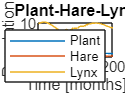

t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;                % end time of simulation [in months]
y0= [0.8 0.2 10];               % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
a1 = 5;               % predation success rate parameter ("how likely that the hare dies if it meets a lynx")
a2= 0.1;              % lynx population increase rate due to predation on tuna ("how much food a linx gets out of eating a hare")
b1= 3;
b2= 2;
d1= 0.4;
d2=0.011;

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

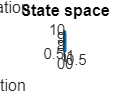

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')

As you can see in the first graph, the lynx population peaks twice. 

The changes made in this simulation were a slight increase in d2 and in increase in the starting lynx population. The reason that we chose to increase d2, is that the lynx population is very stable, because that dead rate was so low. Even when the hare population falls the lynx population will only change a small amount. So to increase insatbility we increased the lynx death rate. 

Then we messed around with the starting lynx population and found that the model was sensitive toward that input. If you were to increase or decrease it you get quite a different result for example:

9: Here the system has a lot less oscilations. 

11: The population first falls for quite a long time than it oscillates upwards. 

The brings us to whether the system is chaotic. The 4 criteria mentioned for a chaotic system are: deterministic, sensitive to initial conditions, bounded and irregular. 

The system is deterministic, because, well, we have mode the model ourselves and you can see the equations right here. (in the plants_hare_lynx_.m file)

The system is also bounded. The grass has a carying capacity of 1, so the grass population wont increase beyond there, the hares grow by eating grass, so are bounded by the amount of grass present, same for the lynx they grow by eating hares, so are bound by their population size. The population also have a lower bound of 0, as you cant have a negative population size. 

I am unsure to call the system irregular, the state space seems quite clean. 

%{ 
%}